cd /home/mic-ciciolla/Documents/università/incompleted/elective/underactuated/hopping-robot-2D/


# One-Legged Hopping Robot

#### Parameters [m] and [kg]

g=9.81;

M1=1; % Leg mass [kg]
M2=10; % Body mass [kg]

I1=1; % Leg moment of Inertia [kg-m^2]
I2=10; % Body moment of Inertia [kg-m^2]

r1=0.5; % [m]
r2=0.4; % [m]

k0=1; % [m]
KL=10^4; % [Nt/m]

KL2=10^5; % [Nt/m]
BL2=125; % [Nt-s/m]

KG=10^3; % [Nt/m]
BG=75; % [Nt-s/m]

% desired jumping height
H = 0.4; %[m]

#### Initial Conditions

ini_theta1 =0;
ini_theta1_d=0;
ini_theta1_dd=0;

ini_theta2 =0;
ini_theta2_d=0;
ini_theta2_dd=0;

% ini_w = k0 = 1 ;
ini_w=1;
ini_w_d=0;

% distance [ Leg CoM -- Hip Joint ]
ini_W = ini_w-r1;

## Foot CoM

ini_x0=0;
ini_x0_d=0;
ini_x0_dd=0;

% height
ini_y0 =0.4; % [m]
ini_y0_d=0;
ini_y0_dd=0;

## Leg CoM

ini_x1=ini_x0+r1*cos(pi/2 - ini_theta1);
ini_x1_d=0;
ini_x1_dd=0;


% height
ini_y1=ini_y0+r1*sin(pi/2 - ini_theta1);
ini_y1_d=0;
ini_y1_dd=0;

## Hip Joint location

ini_xH = ini_x1 + ini_W*cos(pi/2 - ini_theta1);
ini_yH = ini_y1 + ini_W*sin(pi/2 - ini_theta1);

## Body Com

ini_x2=ini_xH + r2*cos(pi/2 - ini_theta2);
ini_x2_d=0;
ini_x2_dd=0;

% height
ini_y2=ini_yH + r2*sin(pi/2 - ini_theta2);
ini_y2_d=0;
ini_y2_dd=0;

## Plotting initial setup

foot(1,1) = ini_x0; foot(1,2) = ini_y0;
leg(1,1) = ini_x1; leg(1,2) = ini_y1;
body(1,1) = ini_x2; body(1,2) = ini_y2;
hip(1,1) = ini_xH; hip(1,2) = ini_yH;

% drawRobot(foot,leg,body,hip)

#### Theta1_desired for torque control (equation 1)

theta1_des=0;

**Desired system energy to jump to height H (equation 14) - costant**

desired_energy = M1*g*(H+r1) + M2*g*(H+k0+r2);

**Maximum compression of leg during stance**

deltaw = (M2*g)/KL + sqrt( ((M2^2*g^2)/KL^2) + 2*g*H*(M1+M2)^2/(M2*KL) );

**Natural frequency the systems tends to oscillate in absence of damping**

omega_n = sqrt(KL/M2);

% Each stance interval has duration Ts
Ts = pi/omega_n; % this is used when calculating a full hopping cycle
% T = Ts + sqrt(8*y0/g); % inside simulink

fprintf(2,"\nInitial conditions:\n\nH = %i\nini_y0 = %u\n\nStarting simulink...\n",H,ini_y0)


Initial conditions:

H = 4.000000e-01
ini_y0 = 4.000000e-01

Starting simulink...


**SIMULINK**

simtime = 10; %simulation time
% Execution of the simulation in Simulink
out=sim('simulink/HoppingModel_Last.slx',simtime); 

Found algebraic loop containing: 
HoppingModel_Last/MODEL/Subsystem_x/Fcn (algebraic variable)
HoppingModel_Last/MODEL/Subsystem_x/x_dd
HoppingModel_Last/MODEL/Subsystem_y/Fcn
HoppingModel_Last/MODEL/Subsystem_y/y_dd
HoppingModel_Last/MODEL/Subsystem_w/Fcn
HoppingModel_Last/MODEL/Subsystem_w/w_dd
Hoppi

**Getting data from Simulink - state variable x**

% theta2 is the only variable carrying out time values (from 0 to simtime)
t = out.theta2.time;

% creating struct variable state ('name',array)
state = struct('y',[],'x',[],'w',[],'theta1',[],'theta2',[],'yd',[],'xd',[],'wd',[],'theta1d',[],'theta2d',[]);

% y0
state.y = out.height;
% y0_pure
state.y0_pure = out.y0_pure;

% y0_pure
state.y2 = out.y2;

% x0
state.x = out.horizontal;
% w
state.w = out.lenght;
% theta1
state.theta1 = out.theta1;
% theta2 
state.theta2 = out.theta2.signals.values;

% y0d
state.yd = out.height_d;

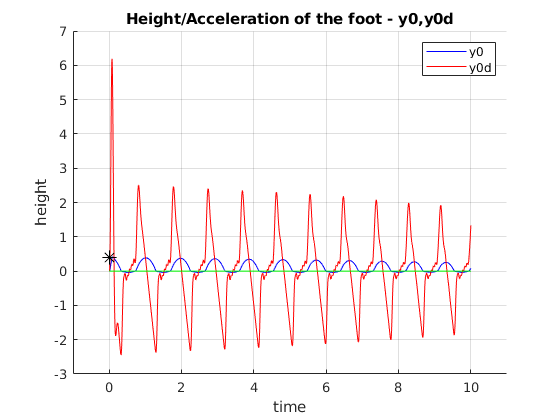

close all

% plot ("Height/Acceleration of the foot - y0,y0d")

figure()
hold on, grid on
plot(t,state.y,"color",'blue')
plot(t,state.yd,"color",'red')

title("Height/Acceleration of the foot - y0,y0d")
plot(0,ini_y0,"marker","*","MarkerSize",10,"Color","k")
plot(t,zeros(size(t)),"color","green")
xlabel("time")
ylabel("height")
xlim([-1,simtime+1])
legend("y0","y0d");

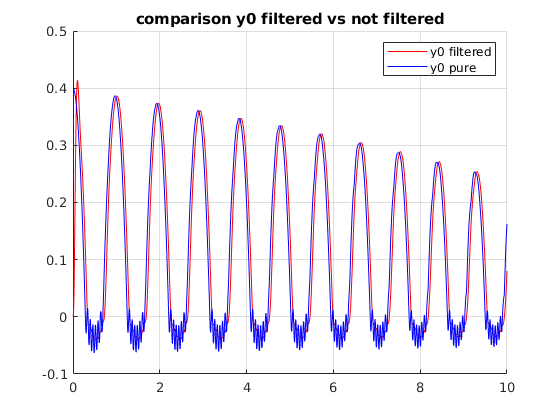


% plot ("comparison y0 filtered vs not filtered")

figure()
hold on, grid on;
plot(t,state.y,"color",'red')
plot(t,state.y0_pure,"color",'blue')
legend("y0 filtered","y0 pure");
title("comparison y0 filtered vs not filtered")

cd simulink/



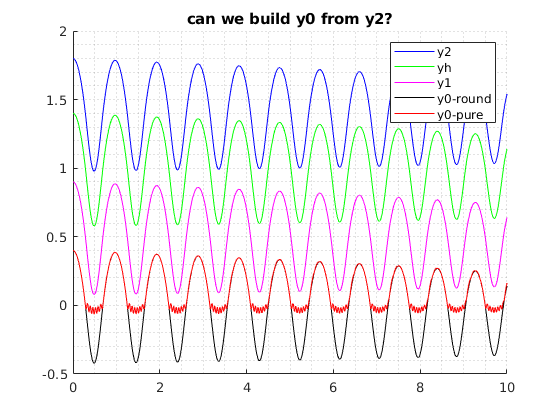

% can we reconstruct y0 from y2, which is clear and not noised?

figure()
hold on, grid minor;

plot(t,state.y2,"color",'blue')

yh = state.y2 - r2*sin(pi/2 - state.theta2);
plot(t,yh,"color",'green')

y1 = yh - (round(state.w) - r1).*sin(pi/2 - state.theta1);
plot(t,y1,"color",'magenta')


y0_r = y1 - r1*sin(pi/2 - state.theta1);
plot(t,y0_r,"color",'black')
plot(t,state.y0_pure,"color",'red')

legend("y2","yh","y1","y0-round","y0-pure")


title("can we build y0 from y2?")

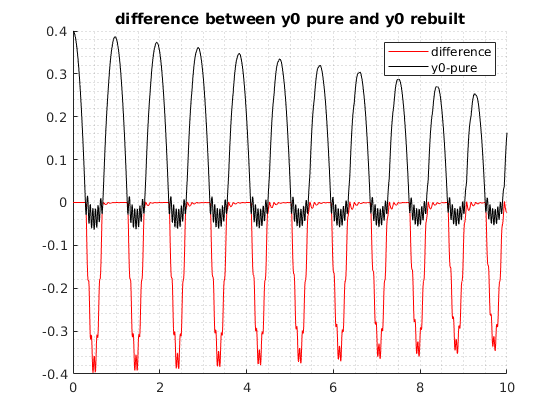


% difference y0 - y0_rebuilt
figure()
hold on, grid minor;
plot(t,round(y0_r - state.y0_pure,5),"color",'red')
plot(t,state.y0_pure,"color",'black')
title("difference between y0 pure and y0 rebuilt")
legend("difference","y0-pure");


% 
figure()
hold on, grid minor;

y0_r_copy = y0_r;
gain = 0.996;
for instant=1:length(y0_r_copy)
    if y0_r_copy(instant)<0
        y0_r_copy(instant) = gain.*y0_r_copy(instant);
    end
end

y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r =     0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


y0_r = 10×1
    0.4000
    0.3999
    0.3995
    0.3989
    0.3980
    0.3969
    0.3956
    0.3940
    0.3922
    0.3901


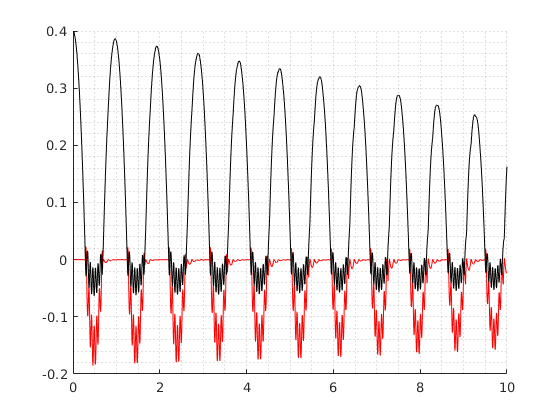


plot(t,round(y0_r_copy - state.y0_pure,5),"color",'red')
plot(t,state.y0_pure,"color",'black')












return

figure()
hold on
grid minor
plot(t,state.w,"color",[1,0.4,0.5])
plot(t,state.y2,"color",'blue')

title("w values during jumping")
legend("w","y2");

disp("THE REAL SPRING ISSUE IS GIVEN BY w OSCILLATIONS")




return

% PEAK POINTS PLOT
figure()
hold on, grid on
title("peak points accuracy")
plot(t,state.y,"color",'blue')

flag = false; % for further uses - not used now
precision = 1; % if 1 = analize each time step sample
interval = t(2) - t(1);

for i=2:precision:length(t)
    if round(state.yd(i),1)==0
        % 0.005 is the step size = t(2) - t(1)
        m = interval*(i-1);
        plot(m,state.y(i),"marker","*","MarkerSize",5,"Color","r")
        flag = true;
    end
end
xlim([-1,simtime+1])

%% STOP HERE TO PREVENT ANIMATION
return

## This is an animated plot of the height of the foot

`run this section: CTRL + ENTER`

figure()
grid on, hold on
xlabel("time")
ylabel("height")
plot(0,ini_y0,"marker","*","MarkerSize",10,"Color","r")
% plot(t,zeros(size(t)),"color","red",'LineWidth',0.1)
legend("initial y0");

% line drawing the foot
anifoot = animatedline;
anifoot.Marker = 'o';
anifoot.MarkerSize = 1.9;
anifoot.LineStyle = ':';
anifoot.LineWidth=0.1;
anifoot.Color = 'k';

% plot(ini_x1,ini_y1,'Color','red',"Marker","x",'LineWidth',3);

% % line drawing the leg
% anleg = animatedline;
% anleg.Marker = 'x';
% anleg.MarkerSize = 0.9;
% anleg.LineStyle = 'none';
% anleg.Color = 'r';

title("Animation of y0")

xlim([-1,31])
ylim([min(state.y)-0.05, max(state.y)+0.1])

% i'm taking one point every 10 to be drawn
for i = 1:10:length(t)
    addpoints(anifoot,t(i),state.y(i))
    drawnow
end

legend("initial y0","height y0");

xlim([-1.0 31.0])
ylim([-0.081 0.400])